# nGaussian Elimination with Backward Substitution

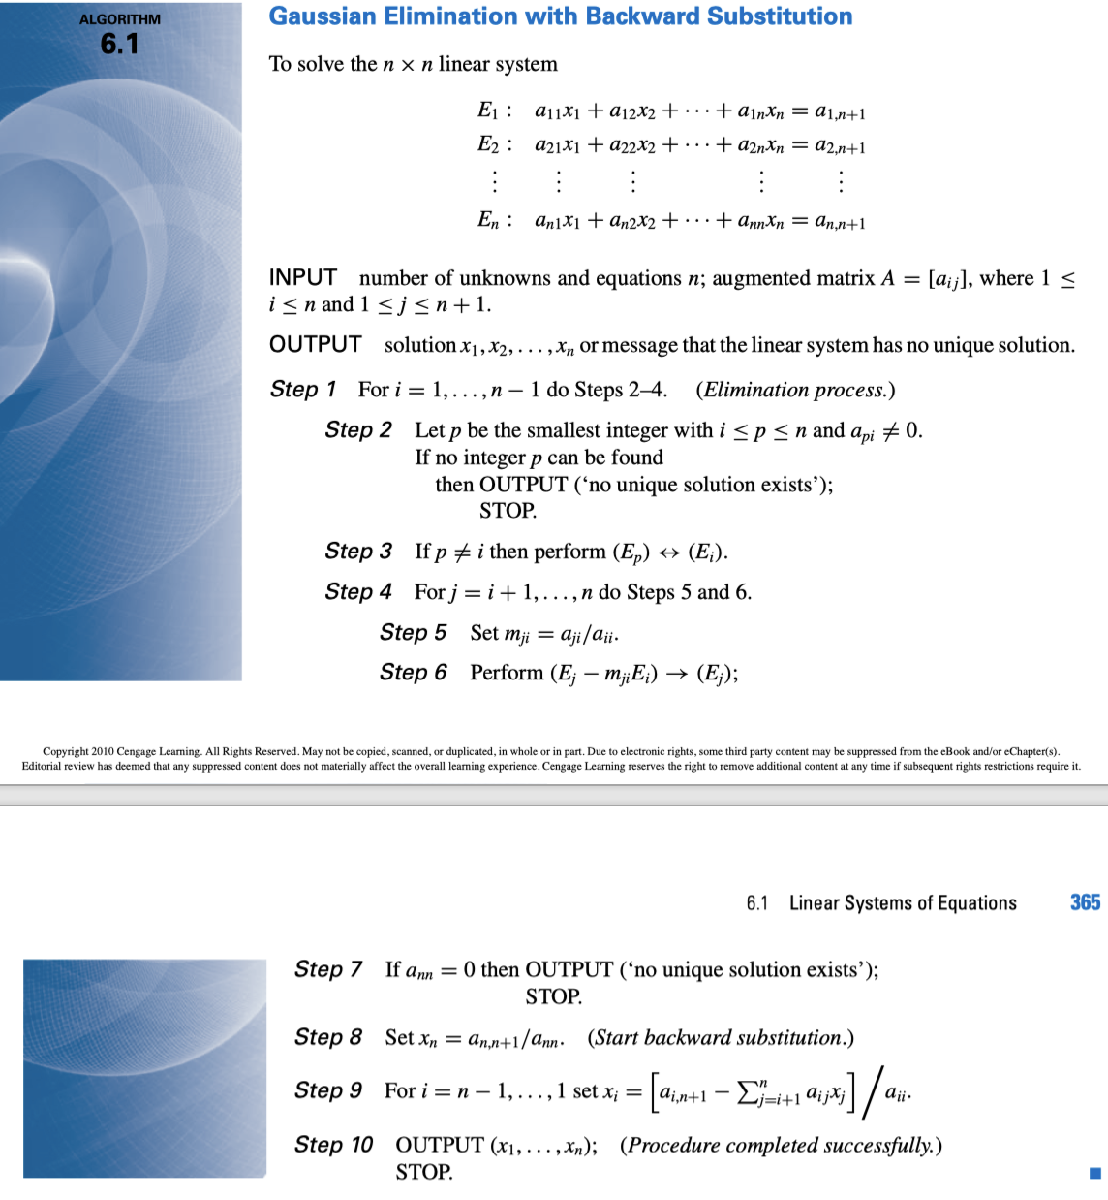

clc;clear;close all;

A=[0,0,-1,1;
    1,1,-1,2;
    -1,-1,2,0;
    1,2,0,2];
B=[0;0;0;0];

rowchange=[];


rowchange =

     []



Ag={};                                                  %Create a cell array to store each matrix
Aau=[A,B];                                              %Generate the augmented matrix
Ag{1}=Aau;                                              %Store the first initial matrix
[n,b]=size(A);
m=[];
for i=1:n-1
    %Check and switch to check pivot to be not 0
    p=i;
    while Aau(p,i)==0 & p <= n+1    
        p=p+1;
    end
    if p==n+1
        disp("No unique solution found, please check");
        break
    end

    %record the row exchange
    rowchange=[rowchange;i,p];
    Atemp=Aau(i,:);
    Aau(i,:)=Aau(p,:);
    Aau(p,:)=Atemp;
    for j=i+1:n
        m(j,i)=Aau(j,i)/Aau(i,i);
        Aau(j,:)=Aau(j,:)-m(j,i).*Aau(i,:);
    end
    Ag{i +1}=Aau;
end

if Aau(n,n)== 0
    disp("No unique Solution Exist");
else


    % Start the backward substituition
    x=[];
    x(n)=Aau(n,n+1)/Aau(n,n);
    
    for i=n-1:-1:1
        sum=0;
        for j=i+1:n
            sum=sum+Aau(i,j)*x(j);
        end
        x(i)=(Aau(i,n+1)-sum)/Aau(i,i);
    end
end


% modify into LU factorization

L2=eye(n);
L1=zeros(4,4);
L1(2:n,1:n-1)=m(2:end,:);
L=L1+L2;
disp(L);
U=Aau(:,1:n);

     1     0     0     0
     0     1     0     0
    -1     0     1     0
     1     0    -1     1






P=eyes(n);
